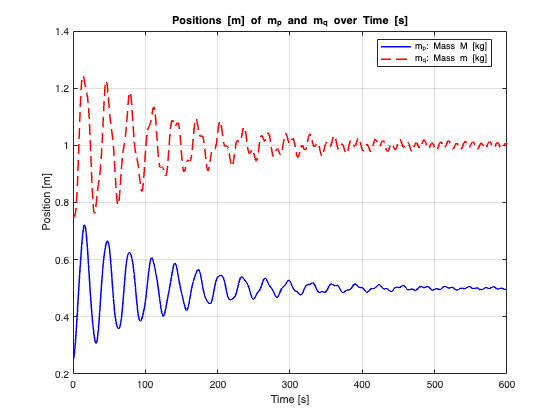

l = 0.5;

xp0 = l / 2;
xq0 = xp0 + l;
dxp0 = 0;
dxq0 = 0;

tspan = [0 600];
y0 = [xp0; xq0; dxp0; dxq0];

[t, y] = ode45(@odefun, tspan, y0);

xp = y(:, 1);
xq = y(:, 2);

figure;
plot(t, xp, 'b-', 'LineWidth', 1.5); hold on;
plot(t, xq, 'r--', 'LineWidth', 1.5);
xlabel('Time [s]');
ylabel('Position [m]');
title('Positions [m] of m_p and m_q over Time [s]');
legend('m_p: Mass M [kg]', 'm_q: Mass m [kg]', 'Location', 'Best');
grid on;

function dydt = odefun(~, y)
    M = 10;
    m = 2;
    k = 0.5;
    b = 0.2;
    l = 0.5;

    xp = y(1);
    xq = y(2);
    dxp = y(3);
    dxq = y(4);

    ddxp = (k * (xq - 2 * xp) - b * dxp) / M;
    ddxq = k * (xp - xq + l) / m;

    dydt = [dxp; dxq; ddxp; ddxq];
end